# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# Second Partial Examination -  A.Y. 2024/2025

**June 6, 2025**

# Design of a Strictly Proper Controller for a Plant with a Parameter Affected by  Interval Uncertainty

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

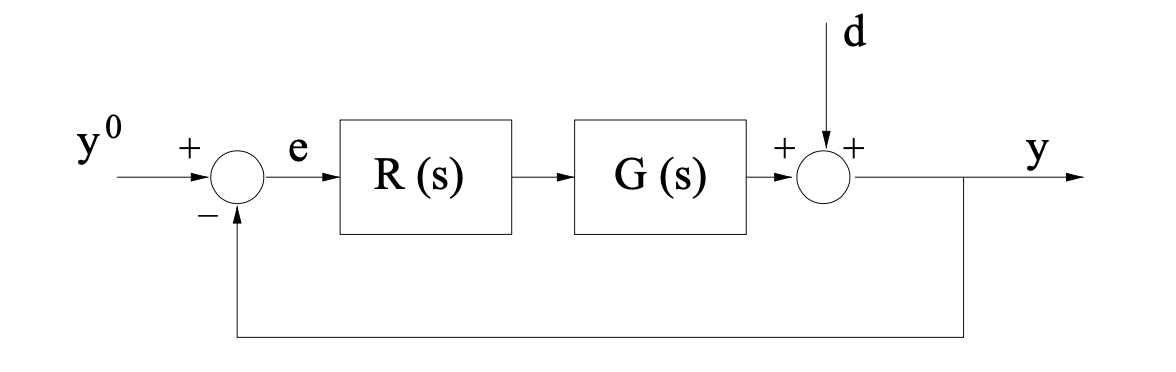	

where $G(s)$ is given by                


$$G(s) = 20\,\frac{(1+5\,s)\,\left(1+\frac{s}{250}\right)}{\left(1+\frac{1.6}{\Omega}\,s+\frac{s^2}{\Omega^2} \right)\,\left(1+\frac{s}{100} \right)}\;,\qquad \Omega \in \big[9\,,\; 16\big]\;\text{rad/sec}$$


**Note**: This means that the system has a transfer function with two complex conjugate poles, whose damping is known exactly ( $\xi = 0.8$) , but whose natural pulsation $\omega_n = \Omega$ is unknown. All that is known is that the natural pulsation $\omega_n$ of the complex conjugate poles takes on a value contained within the assigned range $\big[9\,,\; 16\big]\; \text{rad/s}$. The zeros and the remaining pole are perfectly known.

## **Question**		

**Q1**: Design a **strictly** **proper** **controller** $C(s)$ such that all following requirements are simultaneously met: 

- **Zero steady-state error** in unit step response (closed-loop) $e(\infty) =0$, against disturbances given by 


$$\left\{ \begin{array}{rcl}
y^o(t) &=& 1(t) \\
d(t) &=& A\cdot 1(t)\,,\; A \in \mathbb{R}
\end{array} \right. \quad \Longrightarrow \quad e_{\infty} = 0
$$


            where $\mathbf{1}(t)$ denotes the unit step function;

- **phase** **margin** greater than or equal to $60^\circ$: $\varphi_m \ge 60^{\circ}$;

- **crossover** **angular** **frequency** $\omega_c$ between $1\;\text{rad/sec}$ and $5\;\text{rad/sec}$: $1\le \omega_c \le 5$

### Hint

How to handle the unknown natural pulsation $\omega_n = \Omega$? A good practice is to identify the **worst-case scenario** and design the controller $C(s)$ according to that scenario.

## Solution

Initialisation code (clearing the MATLAB workspace, adding the path of the BodeDiagram subfolder to the MATLAB search-path)

clear variables

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');


### Preliminary Analysis

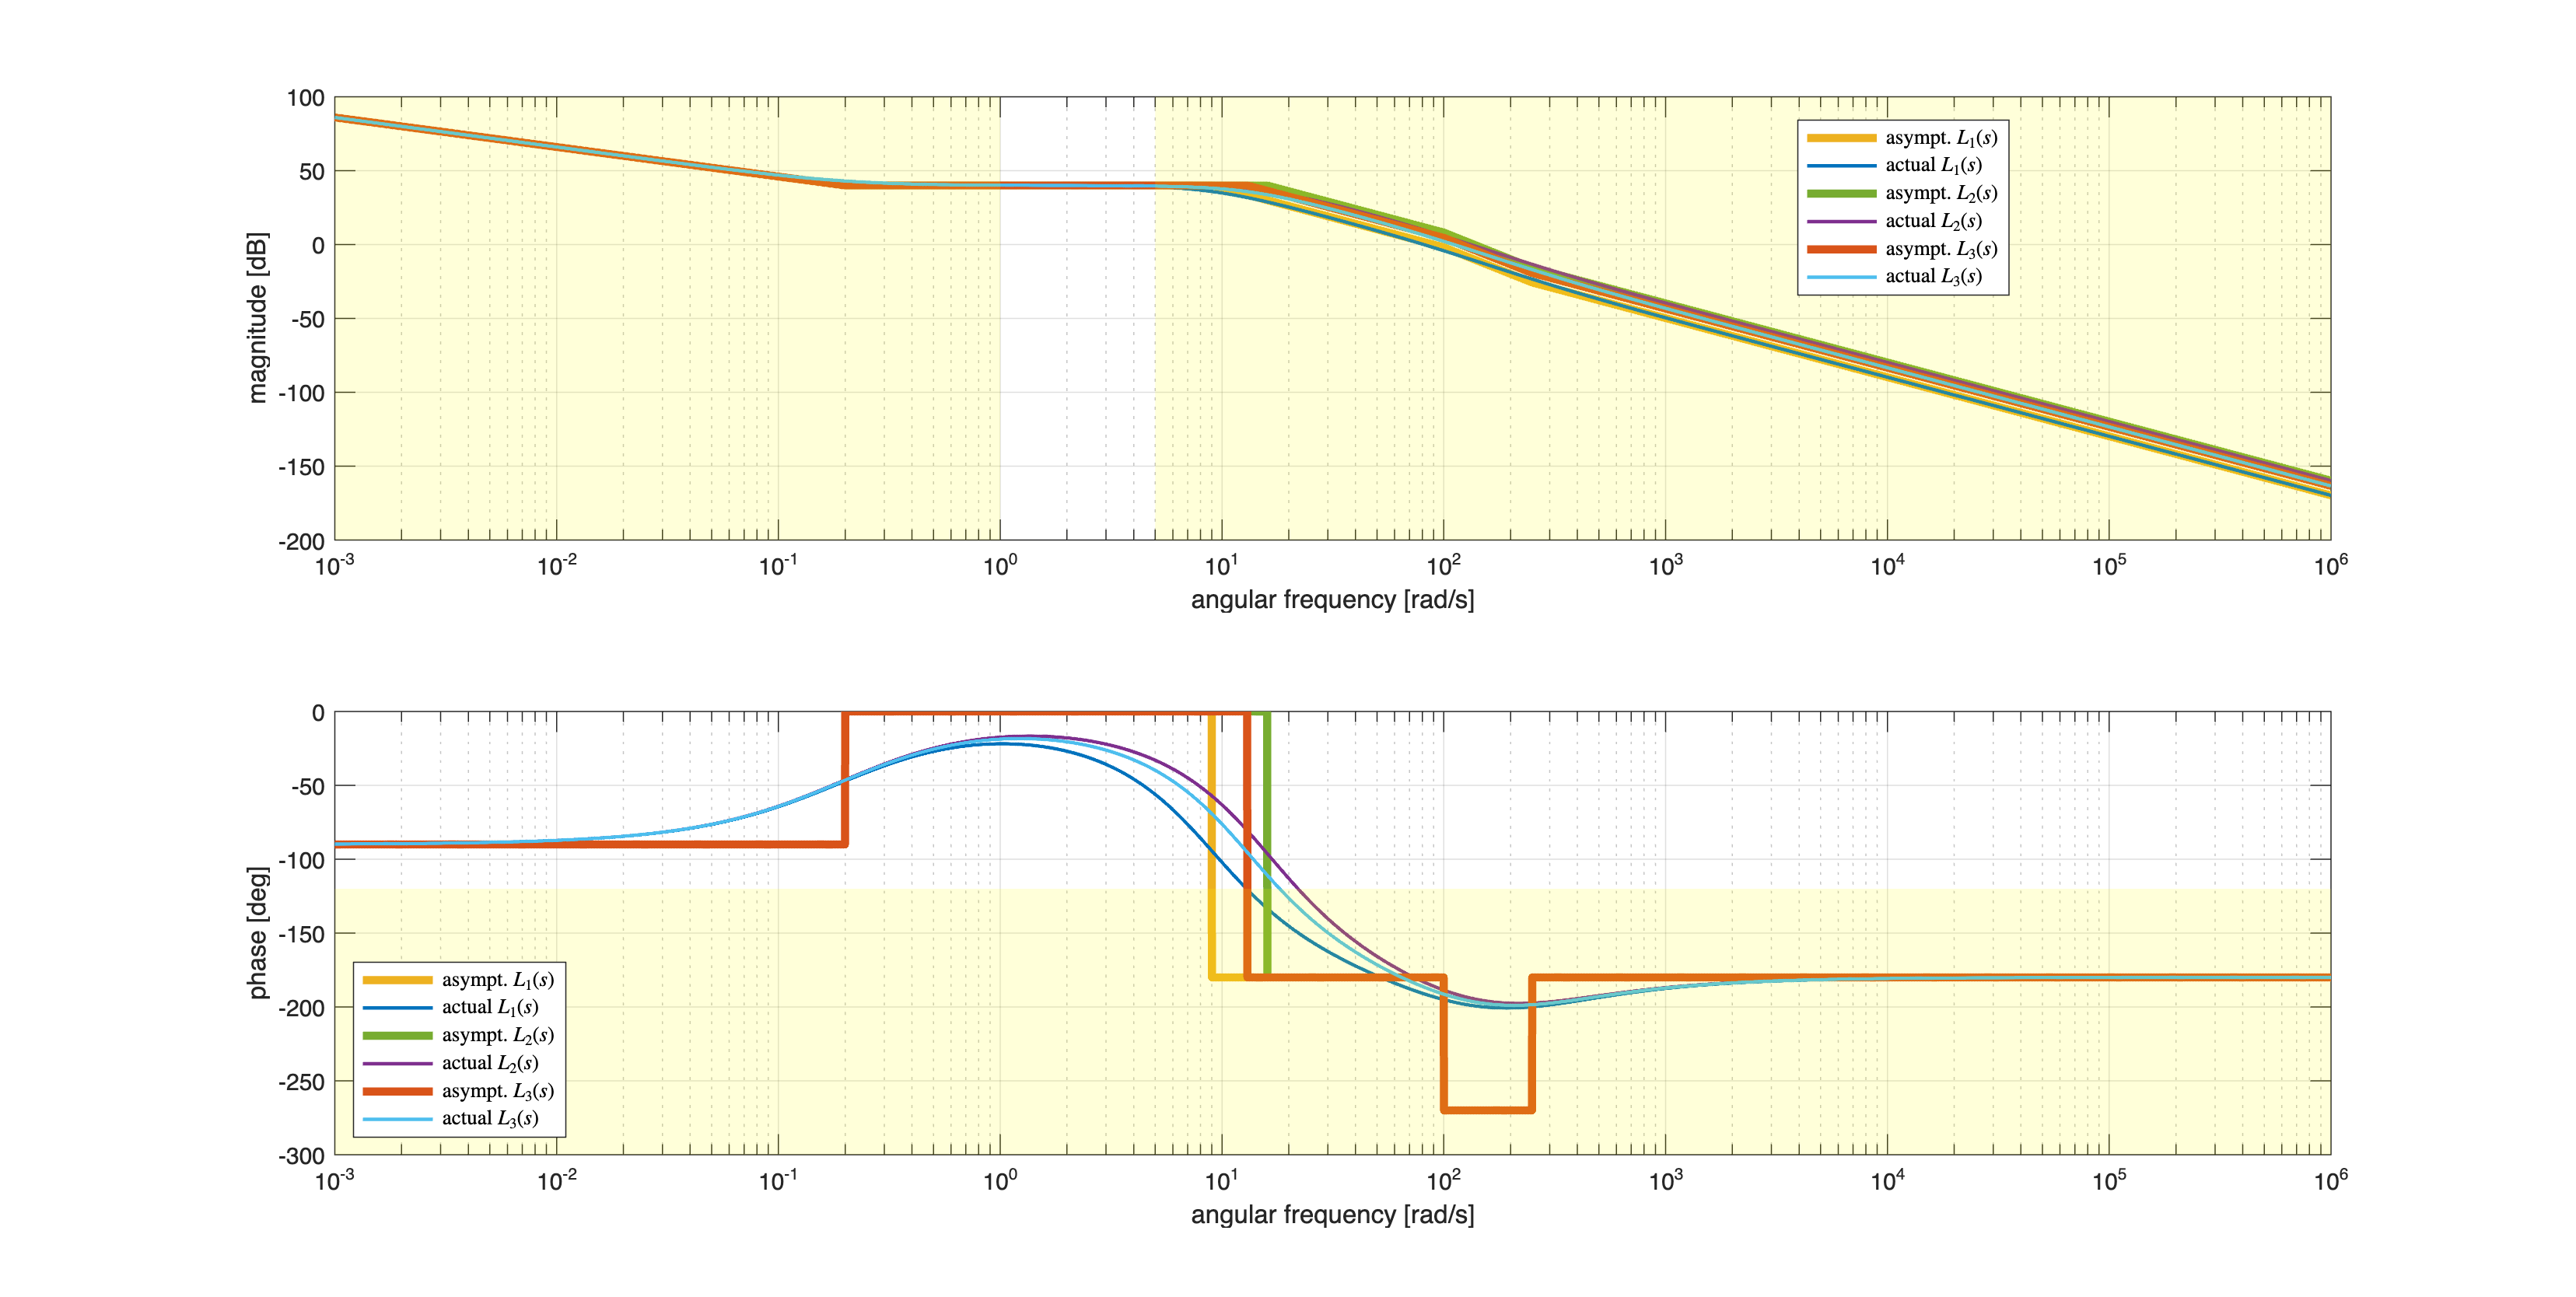

omMIN = 9; omMAX = 16;
omR = 13;

% static regulator
muC = 1;
C1s = muC/s;

Gs1 = 20*(1+5*s)*(1+s/250)/(1+(1.6/omMIN)*s +s^2/omMIN^2)/(1+s/100);
Gs2 = 20*(1+5*s)*(1+s/250)/(1+(1.6/omMAX)*s +s^2/omMAX^2)/(1+s/100);
Gs3 = 20*(1+5*s)*(1+s/250)/(1+(1.6/omR)*s +s^2/omR^2)/(1+s/100);

Ls1 = C1s*Gs1;
Ls2 = C1s*Gs2;
Ls3 = C1s*Gs3;

% the Bode diagrams

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                 

hf = figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.85]);
drawBodediagrams(Ls1, [], Bcolors(2,:) , 3.5, [], Bcolors(1,:) ,1.5, [], hf);
drawBodediagrams(Ls2, [], Bcolors(4,:) , 3.5, [], Bcolors(3,:) ,1.5, [], hf);
[ha1, ha2] = drawBodediagrams(Ls3, [], Bcolors(6,:) , 3.5, [], Bcolors(5,:) ,1.5, [], hf);

phaseM = +60; % the desired minimum phase margin
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design

YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);

% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

omC1 = 1; omC2 = 5; % constraint (Q1.3)
YLIMS = ylim(ha1);
OMLIMs = xlim(ha1);
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
Vert2 = [minOmega1 ,  YLIMS(1); omC1 ,YLIMS(1); ...
         omC1 , YLIMS(2); minOmega1 , YLIMS(2)];
Faces2 = [1  2  3  4];
hold on;
patch(ha1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

Vert3 = [omC2 ,  YLIMS(1); maxOmega1 ,YLIMS(1); ...
         maxOmega1 , YLIMS(2); omC2 , YLIMS(2)];
Faces3 = [1  2  3  4];
hold on;
patch(ha1, 'Faces',Faces3,'Vertices',Vert3,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one


legend(ha1, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'best')
legend(ha2, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'southwest')

% the design problem is feasible!
% the worst-case scenario corresponds to Ls1 --> the phase is the lowest
% one

### Tuning the Controller

According to (Q1.3) and (Q1.2), any angular frequency $\omega \in \big[1\,,\;5\big] \; \text{rad/sec}$ allows to fulfil both the requirements.

Let's tune the gain constant $\mu_C$ with the aim to obtain $\bar \omega = 2$ rad/sec as crossover frequency in the worst-case scenario


$$\left\{\begin{array}{rcl}
C_1(s) &=& \frac{\mu_C}{s} \\
G_1(s) &=& 20\,\frac{(1+5\,s)\,\left(1+\frac{s}{250}\right)}{\left(1+\frac{1.6}{\Omega}\,s+\frac{s^2}{\Omega^2} \right)\,\left(1+\frac{s}{100} \right)}\;,\qquad \Omega = 9\;\text{rad/sec}
\end{array} \right. \quad \Longrightarrow \quad
 L_1(s) = 20\,\mu_C\, \frac{(1+5\,s)\,\left(1+\frac{s}{250}\right)}{s\,\left(1+\frac{16}{90}\,s+\frac{s^2}{81} \right)\,\left(1+\frac{s}{100} \right)}$$


Thus


$$\omega_c = 2 \quad \Longrightarrow \quad  \left|L_1(j2)\right| = 1 = 20\,\mu_C\, \left|\frac{(1+j10)\,\left(1+\frac{j2}{250}\right)}{j2\,\left(1+\frac{16}{90}\,j2-\frac{4}{81} \right)\,\left(1+\frac{j2}{100} \right)} \right|
  \quad  \Longrightarrow \quad \mu_C = ?$$


barOMc1 = 1j*2;
mag_L1s_barOMc1 = abs(freqresp(Ls1, barOMc1));
muC_VAL = 1/mag_L1s_barOMc1

muC_VAL = 0.0101

Verify the performance of the controller $C_1(s)$ in every scenario

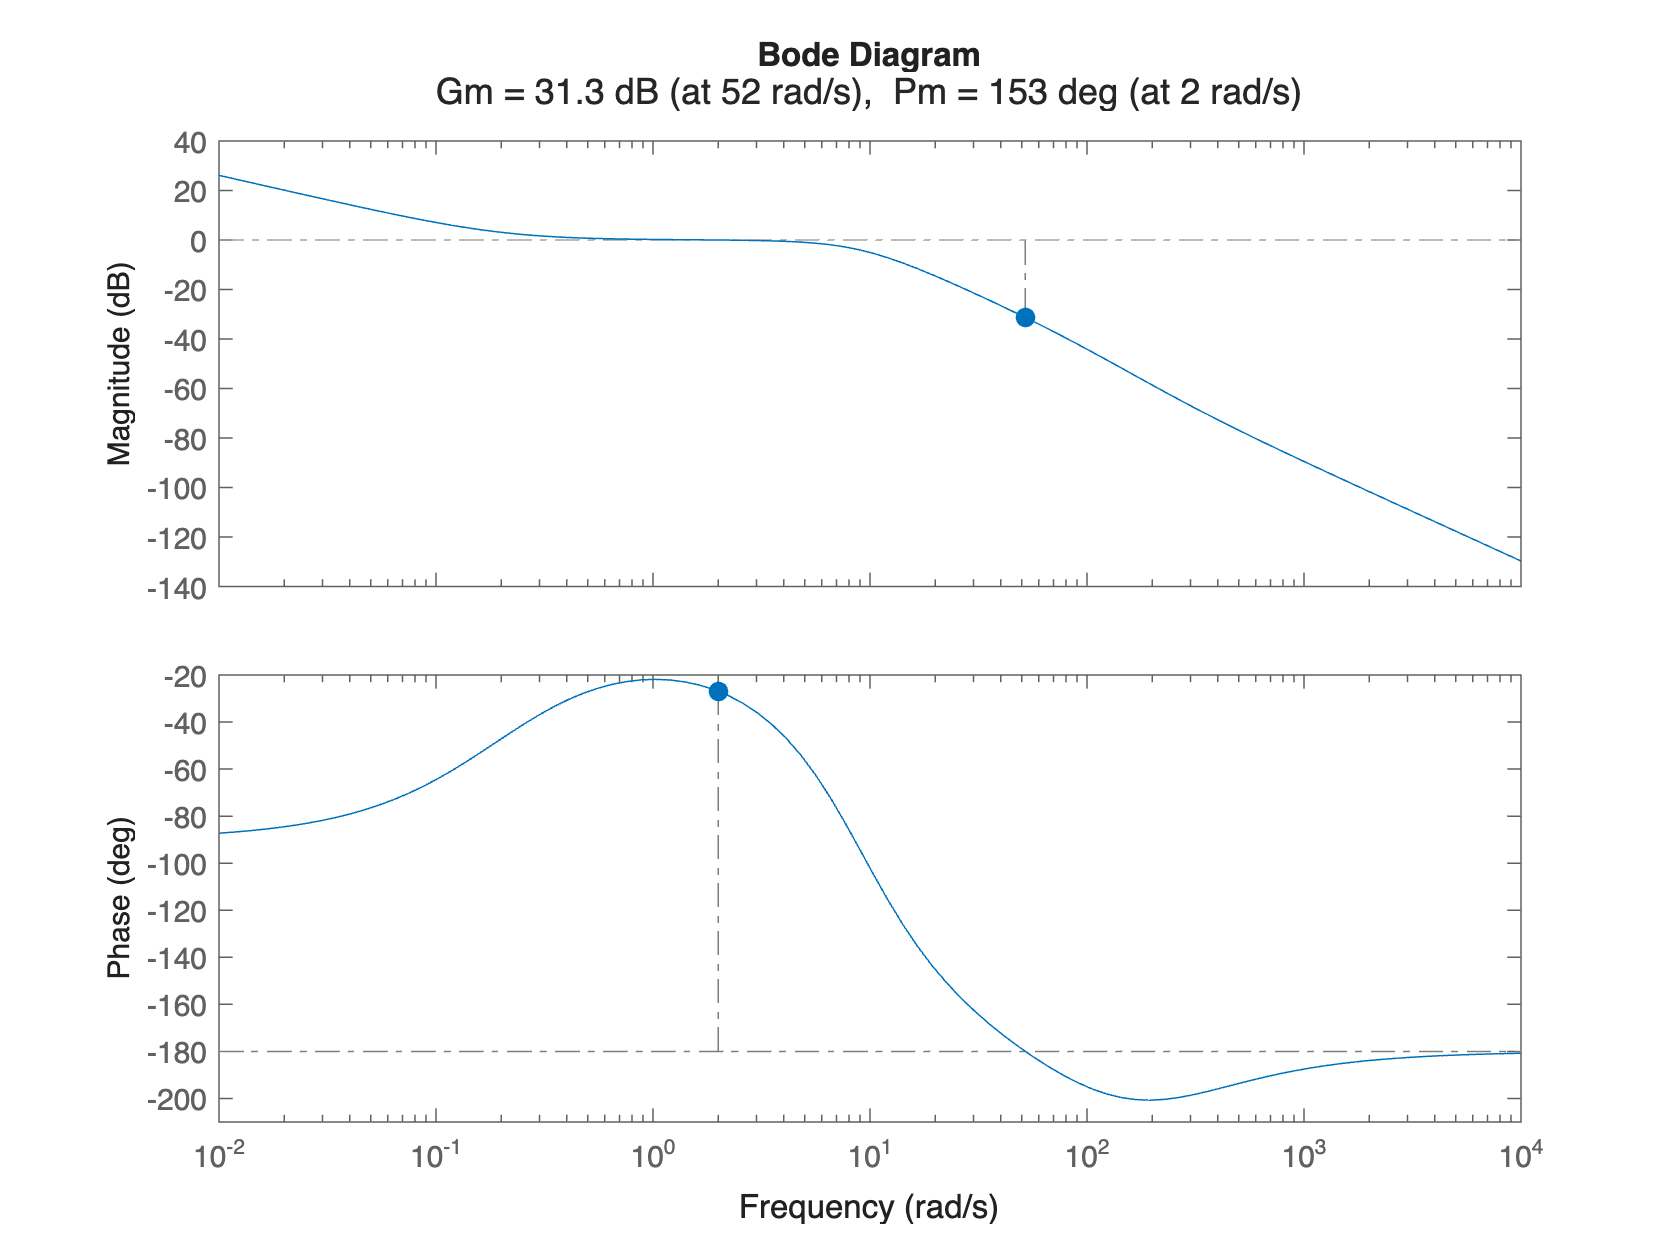

C1s = muC_VAL/s; 

Ls1 = C1s*Gs1;
Ls2 = C1s*Gs2;
Ls3 = C1s*Gs3;

figure;margin(Ls1)

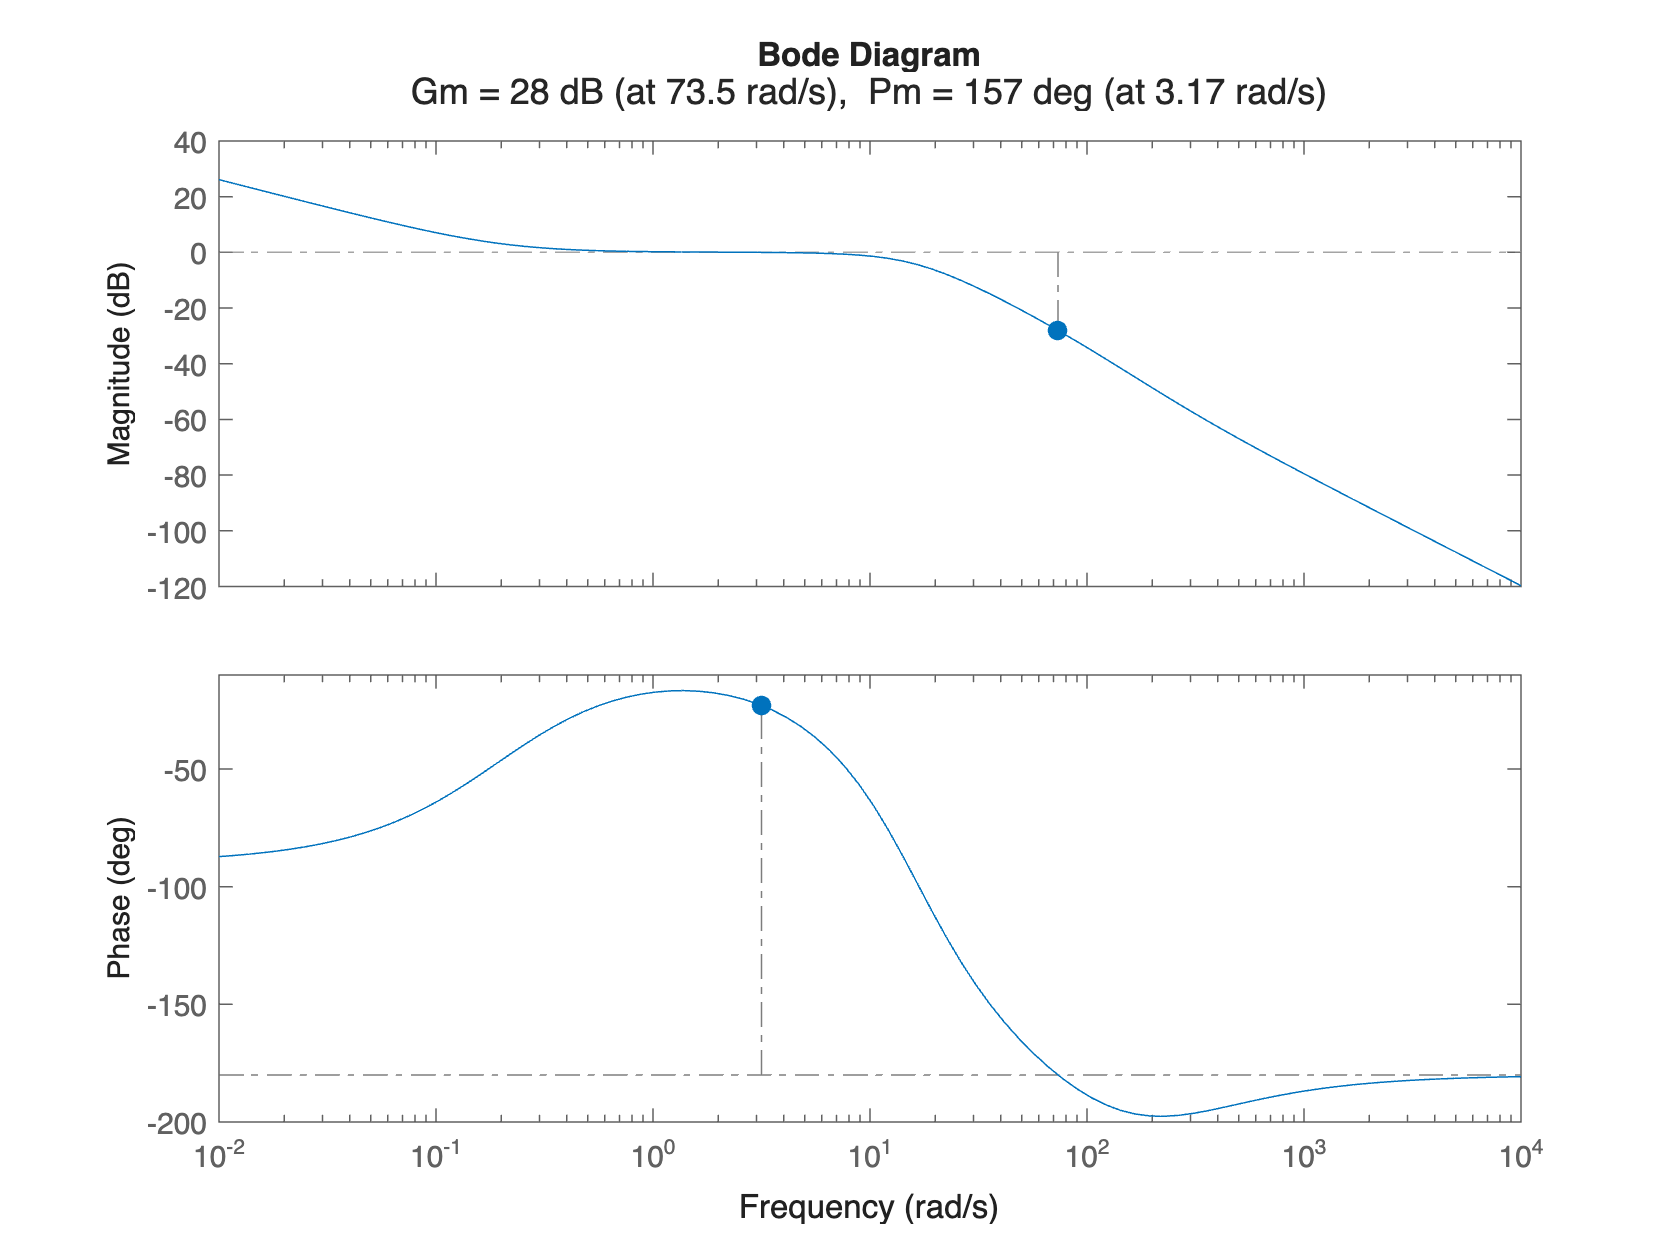


figure; margin(Ls2)

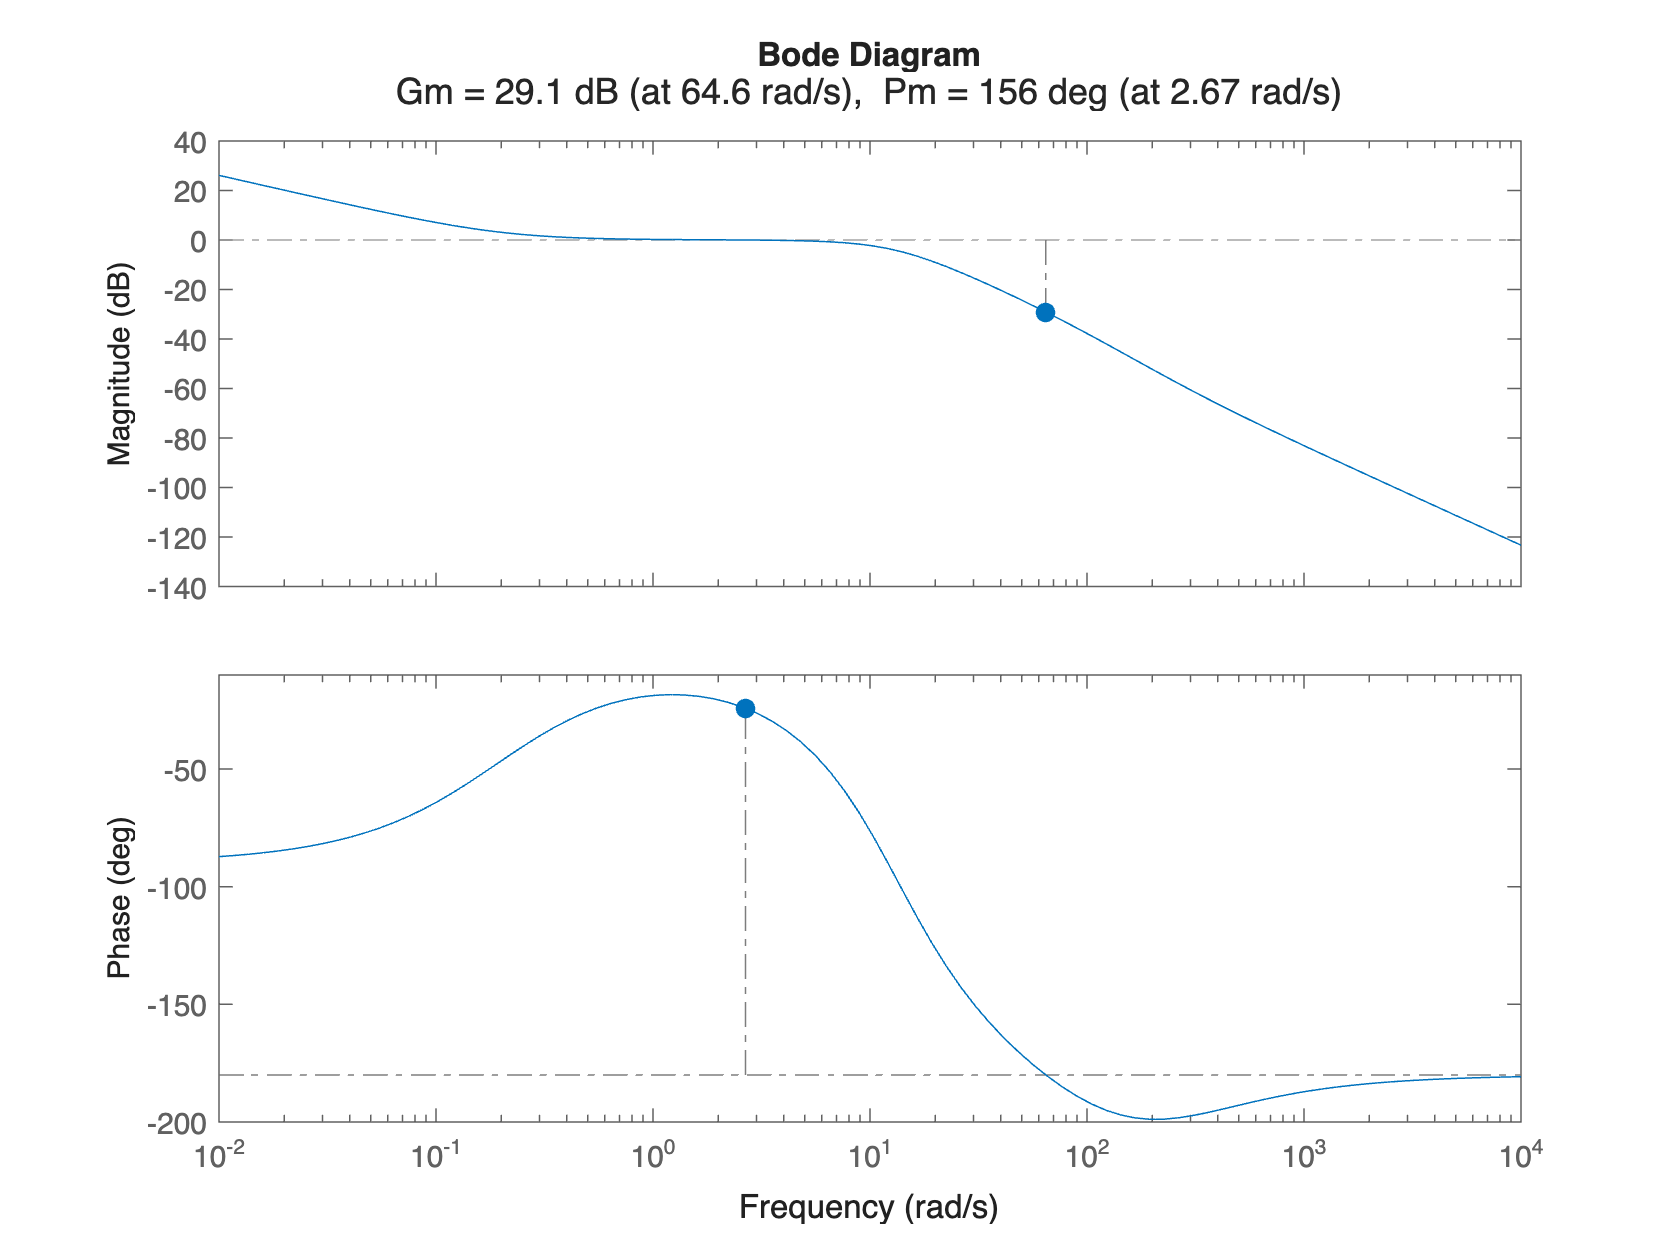


figure;margin(Ls3)

In conclusion, the controller $C_1(s)$ allows to fulfil every requirement.

### Tuning the Controller using the controlSystemDesigner App

% let's create a multi-model structure
Gs = stack(1, Gs1, Gs2, Gs3);

controlSystemDesigner(Gs, C1s)

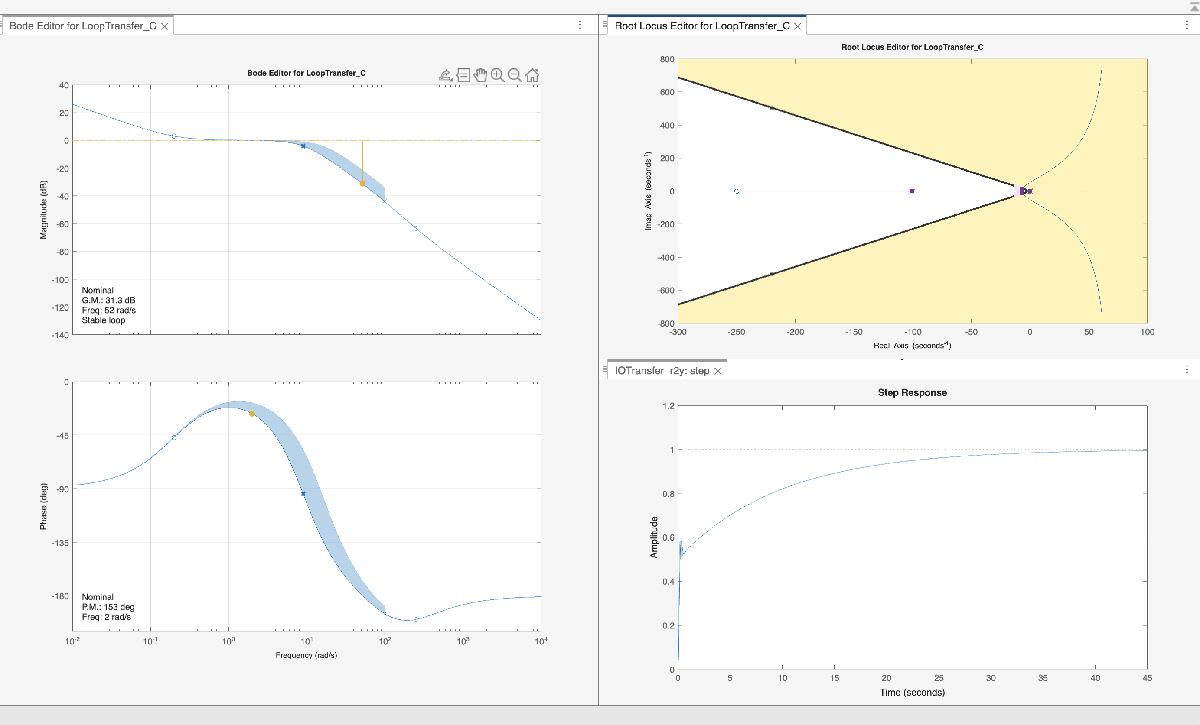

The corresponding controlSystremDesigner session file is `multimodel_solution_2025_06_06_FA_gr_A_ControlSystemDesignerSession.mat`